 吗   第一部分练习题

2(a).

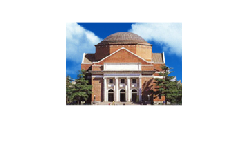

clear all
clc
load("hall.mat")
figure
imshow(hall_color)

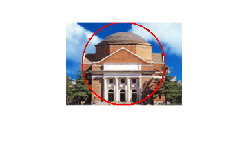

hall_color_copy = hall_color;
[length, width, ~] = size(hall_color_copy);
r = min(length, width) / 2;
x0 = length / 2;
y0 = width / 2;
for len = 1: length
    for wid = 1: width
        dist = sqrt((len - x0) ^ 2 + (wid - y0) ^ 2);
        if abs(dist - r) < 1
            hall_color_copy(len, wid, 1) = 255;
            hall_color_copy(len, wid, 2) = 0;
            hall_color_copy(len, wid, 3) = 0;
        end
    end
end
figure
imshow(hall_color_copy)

2(b).

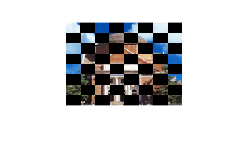

% 8 * 8 Chessboard
clear all
clc
load("hall.mat")
hall_color_copy = hall_color;
[length, width, ~] = size(hall_color_copy);
for len = 1: 8
    for wid = 1: 8
        if mod(len + wid, 2)
            hall_color_copy((len - 1) * length / 8 + 1: len * length / 8, (wid - 1) * width / 8 + 1: wid * width / 8, 1) = 0;
            hall_color_copy((len - 1) * length / 8 + 1: len * length / 8, (wid - 1) * width / 8 + 1: wid * width / 8, 2) = 0;
            hall_color_copy((len - 1) * length / 8 + 1: len * length / 8, (wid - 1) * width / 8 + 1: wid * width / 8, 3) = 0;
        end
    end
end
figure
imshow(hall_color_copy)

第二部分练习题

1.

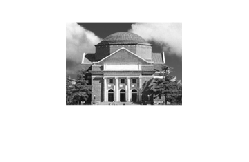

clear all
clc
load("hall.mat")
[length, width, ~] = size(hall_gray);
figure
imshow(hall_gray)


hall_center = hall_gray(length / 4: 3 * length / 4, width / 4: 3 * width / 4);

hall1 = double(hall_center) - 128 .* ones(size(hall_center));
hall1_dct = dct2(hall1);

[len_center, wid_center, ~] = size(hall_center);

hall2_dct = dct2(hall_center) - dct2(128 * ones(len_center, wid_center));
hall2 = idct2(hall2_dct);

mse1 = sum((hall1 - hall2) .^ 2, "all")

mse1 = 5.0044e-24

mse2 = sum((hall1_dct - hall2_dct) .^ 2, "all")

mse2 = 2.9539e-24

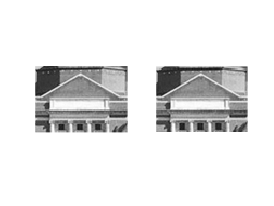


hall2 = hall2 + 128 .* ones(size(hall_center));
figure
subplot(1, 2, 1)
imshow(hall_center)
subplot(1, 2, 2)
imshow(uint8(hall2))

2.

clear all
clc
load("hall.mat")

hall1 = double(hall_gray) - 128 .* ones(size(hall_gray));
hall1_dct = dct2(hall1);
hall1_DCT = DCT2(hall1);
mse = sum((hall1_DCT - hall1_dct) .^ 2, "all")

mse = 1.9577e-20

3.

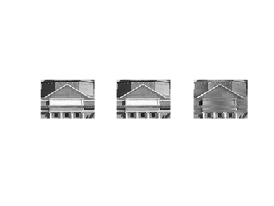

clear all
clc
load("hall.mat")
[length, width, ~] = size(hall_gray);
hall_center = hall_gray(length / 4: 3 * length / 4, width / 4: 3 * width / 4);

hall1 = double(hall_center) - 128 .* ones(size(hall_center));
hall1_dct = dct2(hall1);
rhall_dct = hall1_dct;
lhall_dct = hall1_dct;
rhall_dct(:, end - 3: end) = 0;
rhall = uint8(idct2(rhall_dct) + 128 .* ones(size(hall_center)));
lhall_dct(:, 1: 4) = 0;
lhall = uint8(idct2(lhall_dct) + 128 .* ones(size(hall_center)));
hall1 = hall1 + 128 .* ones(size(hall_center));

figure
subplot(1, 3, 1);
imshow(uint8(hall1))
subplot(1, 3, 2);
imshow(uint8(rhall))
subplot(1, 3, 3);
imshow(uint8(lhall))

4.

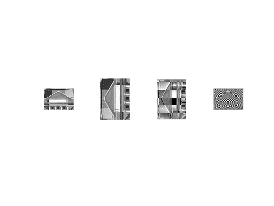

clear all
clc
load("hall.mat")
[length, width, ~] = size(hall_gray);
hall_center = hall_gray(length / 4: 3 * length / 4, width / 4: 3 * width / 4);

hall = double(hall_center) - 128 .* ones(size(hall_center));
hall_dct = dct2(hall);
hallT_dct = hall_dct.';
hall90_dct = rot90(hall_dct);
hall180_dct = rot90(hall90_dct);
hall = uint8(hall + 128 .* ones(size(hall_center)));
hallT = uint8(idct2(hallT_dct) + 128 .* ones(size(hall_center.')));
hall90 = uint8(idct2(hall90_dct) + 128 .* ones(size(rot90(hall_center))));
hall180 = uint8(idct2(hall180_dct) + 128 .* ones(size(hall_center)));

figure
subplot(1, 4, 1);
imshow(hall)
subplot(1, 4, 2);
imshow(hallT)
subplot(1, 4, 3);
imshow(hall90)
subplot(1, 4, 4);
imshow(hall180)

5.

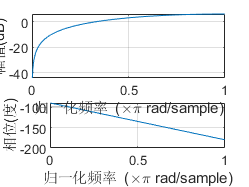

clear all
clc
z = [-1, 1];
p = 1;
figure
freqz(z, p)

7.

clear all
clc
test = [1: 8; 9: 16; 17: 24; 25: 32;
        33: 40; 41: 48; 49: 56; 57: 64];
zigzag(test);

8.

clear all
clc
load("hall.mat")
load("JpegCoeff.mat")
hall_index = getImageIndex(hall_gray, QTAB);
save("hall_index", "hall_index");

9.

clear all
clc
load("hall.mat")
[DC, AC, len, wid] = JPEG_encoding(hall_gray);
save("jpegcodes.mat", "DC", "AC", "len", "wid");

10.

clear all
clc
load("hall.mat")

[DC, AC, len, wid] = JPEG_encoding(hall_gray);
CR = 8 * len * wid / (length(DC) + length(AC))

CR = 6.4188

11.

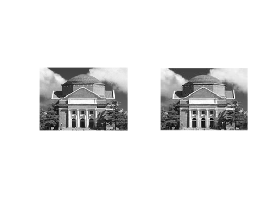

clear all
clc
load("hall.mat")
load("jpegcodes.mat")

image = JPEG_decoding(DC, AC, len, wid);
figure
subplot(1, 2, 1);
imshow(hall_gray)
subplot(1, 2, 2);
imshow(image)


MSE = sum((image - hall_gray) .^ 2, "all") / (len * wid);
PSNR = 10 * log10(255 * 255 / MSE)

PSNR = 34.8926

12.

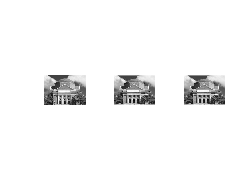

clear all
clc
load("hall.mat")
load("jpegcodes.mat")

image1 = JPEG_decoding(DC, AC, len, wid);
[DC2, AC2, len2, wid2] = JPEG_encoding2(hall_gray);
image2 = JPEG_decoding2(DC2, AC2, len2, wid2);
figure
subplot(1, 3, 1);
imshow(hall_gray)
subplot(1, 3, 2);
imshow(image1)
subplot(1, 3, 3);
imshow(image2)


CR1 = 8 * len * wid / (length(DC) + length(AC))

CR1 = 6.4188

CR2 = 8 * len2 * wid2 / (length(DC2) + length(AC2))

CR2 = 4.4081


MSE1 = sum((image1 - hall_gray) .^ 2, "all") / (len * wid);
PSNR1 = 10 * log10(255 * 255 / MSE1)

PSNR1 = 34.8926

MSE2 = sum((image2 - hall_gray) .^ 2, "all") / (len2 * wid2);
PSNR2 = 10 * log10(255 * 255 / MSE2)

PSNR2 = 37.3208

13.

clear all
clc
load("snow.mat")
[DC, AC, len, wid] = JPEG_encoding(snow);
image = JPEG_decoding(DC, AC, len, wid);

CR = 8 * len * wid / (length(DC) + length(AC))

CR = 3.6407

MSE = sum((image - snow) .^ 2, "all") / (len * wid);
PSNR = 10 * log10(255 * 255 / MSE)

PSNR = 29.5614

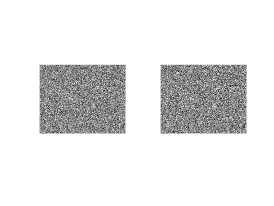


figure
subplot(1, 2, 1);
imshow(snow)
subplot(1, 2, 2);
imshow(image)

第三部分练习题

1.

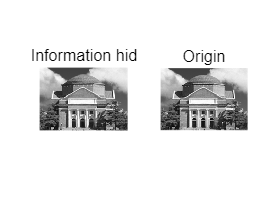

clear all
clc
load("hall.mat")
hall = hall_gray;
info = dec2bin('MATLAB') - '0';
[len, wid, ~] = size(info);
for i = 1: len * wid
    hall(i) = bitset(hall(i), 1, info(i));
end

infoExtract = zeros([len, wid]);
for i = 1: len * wid
    infoExtract(i) = bitset(infoExtract(i), 1, bitget(hall(i), 1));
end
infoExtract = char(bin2dec(char(infoExtract + '0')));

[DC, AC, L, W] = JPEG_encoding(hall);
image = JPEG_decoding(DC, AC, L, W);
infoAfterJPEG = zeros([len, wid]);
for i = 1: len * wid
    infoAfterJPEG(i) = bitset(infoAfterJPEG(i), 1, bitget(image(i), 1));
end
infoAfterJPEG == info;
infoAfterJPEG = char(bin2dec(char(infoAfterJPEG + '0')));

figure
subplot(1, 2, 1);
imshow(uint8(hall))
title("Information hid")
subplot(1, 2, 2);
imshow(hall_gray)
title("Origin")

2.(1)

clear all
clc
load("hall.mat")
load("JpegCoeff.mat")
info = dec2bin('MATLAB') - '0';

image_temp = double(hall_gray) - 128 .* ones(size(hall_gray));
image_block = blockproc(image_temp, [8, 8], @(M) round(dct2(M.data) ./ QTAB));
[len, wid, ~] = size(info);
[len1, wid1, ~] = size(hall_gray);
dis = len1 * wid1 / len / wid;
for i = 0: len * wid - 1
    for j = 1: len * wid: len1 * wid1
        image_block(i + j) = bitset(abs(image_block(i + j)), 1, info(i + 1));
    end
end
image_block = blockproc(image_block, [8, 8], @(M) zigzag(M.data));

[len, wid, ~] = size(image_block);
image_index = zeros([64, len * wid / 64]);
for i = 1: len / 64
    image_index(:, (i - 1) * wid + 1: i * wid) = image_block(64 * (i - 1) + 1: 64 * i, :);
end

DC_diff = [image_index(1, 1), image_index(1, 1: end - 1) - image_index(1, 2: end)];
DC_category = min(ceil(log2(abs(DC_diff) + 1)), 11);

DC = [];
for i = 1: length(DC_diff)
    DC_Huffman = DCTAB(DC_category(i) + 1, 2: DCTAB(DC_category(i) + 1, 1) + 1).';
    DC_bin = (dec2bin(abs(DC_diff(i))) - '0').';
    if DC_diff(i) < 0
	    DC_bin = ~DC_bin;
    end
    DC = [DC; DC_Huffman; DC_bin];
end

AC_index = image_index(2: end, :);
AC_category = min(ceil(log2(abs(AC_index) + 1)), 10);

ZRL = [1; 1; 1; 1; 1; 1; 1; 1; 0; 0; 1];
EOB = [1; 0; 1; 0];
[len, wid] = size(AC_category);
AC = [];
for i = 1: wid
    Run = 0;
    sixteenTimes = 0;
    for j = 1: len
        if AC_category(j, i) == 0
            Run = Run + 1;
            if Run == 16
                sixteenTimes = sixteenTimes + 1;
                Run = 0;
            end
        else
            while sixteenTimes > 0
                AC = [AC; ZRL];
                sixteenTimes = sixteenTimes - 1;
            end
            AC_Huffman = ACTAB(10 * Run + AC_category(j, i), 4: ACTAB(10 * Run + AC_category(j, i), 3) + 3).';
            AC_bin = (dec2bin(abs(AC_index(j, i))) - '0').';
            if AC_index(j, i) < 0
                AC_bin = ~AC_bin;
            end
            AC = [AC; AC_Huffman; AC_bin];
            Run = 0;
        end
    end
    AC = [AC; EOB];
end

[len, wid, ~] = size(hall_gray);
DC_diff = zeros([len * wid / 64, 1]);
index = 1;
count = 1;
i = 2;
while i <= length(DC)
    for j = 1: size(DCTAB, 1)
        if isequal(DC(index: i), DCTAB(j, 2: DCTAB(j, 1) + 1)')
            if j == 1
                DC_diff(count) = 0;
                index = i + 2;
                i = index;
                count = count + 1;
                break;
            else
                DC_bin = DC(i + 1: i + j - 1)';
                if DC_bin(1)
                    DC_diff(count) = bin2dec(char(DC_bin + '0'));
                else
                    DC_diff(count) = -bin2dec(char(~DC_bin + '0'));
                end
                index = i + j;
                i = index;
                count = count + 1;
                break;
            end
        end
    end
    i = i + 1;
end

DC_index = zeros(size(DC_diff));
DC_index(1) = DC_diff(1);
for i = 2: size(DC_index, 1)
    DC_index(i) = DC_index(i - 1) - DC_diff(i);
end

AC_index = zeros([63, len * wid / 64]);
index = 1;
rowCount = 1;
colCount = 1;
i = 2;
while i <= length(AC)
    if isequal(AC(index: i), EOB)
        colCount = colCount + 1;
        rowCount = 1;
        index = i + 1;
        i = index;
    elseif isequal(AC(index: i), ZRL)
        rowCount = rowCount + 16;
        index = i + 1;
        i = index;
    else
        for j = 1: size(ACTAB, 1)
            if isequal(AC(index: i), ACTAB(j, 4: ACTAB(j, 3) + 3)')
                rowCount = rowCount + ACTAB(j, 1);
                AC_bin = AC(i + 1: i + ACTAB(j, 2))';
                if AC_bin(1)
                    AC_index(rowCount, colCount) = bin2dec(char(AC_bin + '0'));
                else
                    AC_index(rowCount, colCount) = -bin2dec(char(~AC_bin + '0'));
                end
                rowCount = rowCount + 1;
                index = i + ACTAB(j, 2) + 1;
                i = index;
                break;
            end
        end
    end
    i = i + 1;
end
image_index = [DC_index'; AC_index];
image_block = zeros([len * 8, wid / 8]);
% 一次从image_index搬wid / 8(168 / 8 = 21)个块到image_block
for i = 1: len / 8
    image_block((i - 1) * 64 + 1: i * 64, :) = image_index(:, (i - 1) .* wid / 8 + 1: i * wid / 8);
end

image_block = blockproc(image_block, [64, 1], @(M)(izigzag(M.data)));

[len, wid, ~] = size(info);
infoAfterJPEG = zeros([len, wid]);
res = [];
i = 0;
while i < dis
    for j = 1: len * wid
        bitget(image_block(j + i * len * wid), 1);
        infoAfterJPEG(j) = bitset(infoAfterJPEG(j), 1, bitget(image_block(j + i * len * wid), 1));
        temp = char(bin2dec(char(infoAfterJPEG + '0')));
    end
    res = [res, temp];
    i = i + 1;
end
res

res = 6×480 char 数组
    'MMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMM'
    'AAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAA'
    'T


image = uint8(blockproc(image_block, [8, 8], @(M)(idct2(M.data .* QTAB))) + 128);
[len, wid, ~] = size(hall_gray);
CR = 8 * len * wid / (length(DC) + length(AC))

CR = 3.2050

MSE = sum((image - hall_gray) .^ 2, "all") / (len * wid);
PSNR = 10 * log10(255 * 255 / MSE)

PSNR = 26.2799

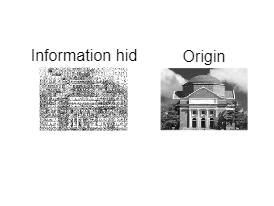


figure
subplot(1, 2, 1);
imshow(image)
title("Information hid")
subplot(1, 2, 2);
imshow(hall_gray)
title("Origin")

2.(2)

clear all
clc
load("hall.mat")
load("JpegCoeff.mat")
info = dec2bin('MATLAB') - '0';

image_temp = double(hall_gray) - 128 .* ones(size(hall_gray));
image_block = blockproc(image_temp, [8, 8], @(M) round(dct2(M.data) ./ QTAB));
[len, wid, ~] = size(info);
for i = 1: len * wid
    image_block(i) = bitset(abs(image_block(i)), 1, info(i));
end

image_block = blockproc(image_block, [8, 8], @(M) zigzag(M.data));

[len, wid, ~] = size(image_block);
image_index = zeros([64, len * wid / 64]);
for i = 1: len / 64
    image_index(:, (i - 1) * wid + 1: i * wid) = image_block(64 * (i - 1) + 1: 64 * i, :);
end

DC_diff = [image_index(1, 1), image_index(1, 1: end - 1) - image_index(1, 2: end)];
DC_category = min(ceil(log2(abs(DC_diff) + 1)), 11);

DC = [];
for i = 1: length(DC_diff)
    DC_Huffman = DCTAB(DC_category(i) + 1, 2: DCTAB(DC_category(i) + 1, 1) + 1).';
    DC_bin = (dec2bin(abs(DC_diff(i))) - '0').';
    if DC_diff(i) < 0
	    DC_bin = ~DC_bin;
    end
    DC = [DC; DC_Huffman; DC_bin];
end

AC_index = image_index(2: end, :);
AC_category = min(ceil(log2(abs(AC_index) + 1)), 10);

ZRL = [1; 1; 1; 1; 1; 1; 1; 1; 0; 0; 1];
EOB = [1; 0; 1; 0];
[len, wid] = size(AC_category);
AC = [];
for i = 1: wid
    Run = 0;
    sixteenTimes = 0;
    for j = 1: len
        if AC_category(j, i) == 0
            Run = Run + 1;
            if Run == 16
                sixteenTimes = sixteenTimes + 1;
                Run = 0;
            end
        else
            while sixteenTimes > 0
                AC = [AC; ZRL];
                sixteenTimes = sixteenTimes - 1;
            end
            AC_Huffman = ACTAB(10 * Run + AC_category(j, i), 4: ACTAB(10 * Run + AC_category(j, i), 3) + 3).';
            AC_bin = (dec2bin(abs(AC_index(j, i))) - '0').';
            if AC_index(j, i) < 0
                AC_bin = ~AC_bin;
            end
            AC = [AC; AC_Huffman; AC_bin];
            Run = 0;
        end
    end
    AC = [AC; EOB];
end

[len, wid, ~] = size(hall_gray);
DC_diff = zeros([len * wid / 64, 1]);
index = 1;
count = 1;
i = 2;
while i <= length(DC)
    for j = 1: size(DCTAB, 1)
        if isequal(DC(index: i), DCTAB(j, 2: DCTAB(j, 1) + 1)')
            if j == 1
                DC_diff(count) = 0;
                index = i + 2;
                i = index;
                count = count + 1;
                break;
            else
                DC_bin = DC(i + 1: i + j - 1)';
                if DC_bin(1)
                    DC_diff(count) = bin2dec(char(DC_bin + '0'));
                else
                    DC_diff(count) = -bin2dec(char(~DC_bin + '0'));
                end
                index = i + j;
                i = index;
                count = count + 1;
                break;
            end
        end
    end
    i = i + 1;
end

DC_index = zeros(size(DC_diff));
DC_index(1) = DC_diff(1);
for i = 2: size(DC_index, 1)
    DC_index(i) = DC_index(i - 1) - DC_diff(i);
end

AC_index = zeros([63, len * wid / 64]);
index = 1;
rowCount = 1;
colCount = 1;
i = 2;
while i <= length(AC)
    if isequal(AC(index: i), EOB)
        colCount = colCount + 1;
        rowCount = 1;
        index = i + 1;
        i = index;
    elseif isequal(AC(index: i), ZRL)
        rowCount = rowCount + 16;
        index = i + 1;
        i = index;
    else
        for j = 1: size(ACTAB, 1)
            if isequal(AC(index: i), ACTAB(j, 4: ACTAB(j, 3) + 3)')
                rowCount = rowCount + ACTAB(j, 1);
                AC_bin = AC(i + 1: i + ACTAB(j, 2))';
                if AC_bin(1)
                    AC_index(rowCount, colCount) = bin2dec(char(AC_bin + '0'));
                else
                    AC_index(rowCount, colCount) = -bin2dec(char(~AC_bin + '0'));
                end
                rowCount = rowCount + 1;
                index = i + ACTAB(j, 2) + 1;
                i = index;
                break;
            end
        end
    end
    i = i + 1;
end
image_index = [DC_index'; AC_index];
image_block = zeros([len * 8, wid / 8]);
% 一次从image_index搬wid / 8(168 / 8 = 21)个块到image_block
for i = 1: len / 8
    image_block((i - 1) * 64 + 1: i * 64, :) = image_index(:, (i - 1) .* wid / 8 + 1: i * wid / 8);
end

image_block = blockproc(image_block, [64, 1], @(M)(izigzag(M.data)));
[len, wid, ~] = size(info);
infoAfterJPEG = zeros([len, wid]);
for i = 1: len * wid
    infoAfterJPEG(i) = bitset(infoAfterJPEG(i), 1, bitget(image_block(i), 1));
end
infoAfterJPEG = char(bin2dec(char(infoAfterJPEG + '0')))

infoAfterJPEG = 6×1 char 数组
    'M'
    'A'
    'T'
    'L'
    'A'
    'B'



image = uint8(blockproc(image_block, [8, 8], @(M)(idct2(M.data .* QTAB))) + 128);
[len, wid, ~] = size(hall_gray);
CR = 8 * len * wid / (length(DC) + length(AC))

CR = 6.4033

MSE = sum((image - hall_gray) .^ 2, "all") / (len * wid);
PSNR = 10 * log10(255 * 255 / MSE)

PSNR = 34.8669

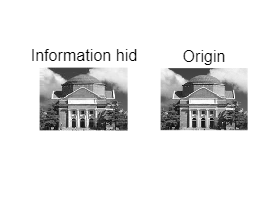

figure
subplot(1, 2, 1);
imshow(image)
title("Information hid")
subplot(1, 2, 2);
imshow(hall_gray)
title("Origin")

2.(3)

clear all
clc
load("hall.mat")
load("JpegCoeff.mat")

image_temp = double(hall_gray) - 128 .* ones(size(hall_gray));
image_block = blockproc(image_temp, [8, 8], @(M) zigzag(round(dct2(M.data) ./ QTAB)));
[len, wid, ~] = size(image_block);

info = rand([len * wid / 64, 1]);
info(info >= 0.5) = 1;
info(info < 0.5) = -1;
j = 0;
for i = 1: len * wid / 64
    while image_block(64 * i - j) == 0
        j = j + 1;
    end
    image_block(64 * i - j) = info(i);
    j = 0;
end

image_index = zeros([64, len * wid / 64]);
for i = 1: len / 64
    image_index(:, (i - 1) * wid + 1: i * wid) = image_block(64 * (i - 1) + 1: 64 * i, :);
end

DC_diff = [image_index(1, 1), image_index(1, 1: end - 1) - image_index(1, 2: end)];
DC_category = min(ceil(log2(abs(DC_diff) + 1)), 11);

DC = [];
for i = 1: length(DC_diff)
    DC_Huffman = DCTAB(DC_category(i) + 1, 2: DCTAB(DC_category(i) + 1, 1) + 1).';
    DC_bin = (dec2bin(abs(DC_diff(i))) - '0').';
    if DC_diff(i) < 0
	    DC_bin = ~DC_bin;
    end
    DC = [DC; DC_Huffman; DC_bin];
end

AC_index = image_index(2: end, :);
AC_category = min(ceil(log2(abs(AC_index) + 1)), 10);

ZRL = [1; 1; 1; 1; 1; 1; 1; 1; 0; 0; 1];
EOB = [1; 0; 1; 0];
[len, wid] = size(AC_category);
AC = [];
for i = 1: wid
    Run = 0;
    sixteenTimes = 0;
    for j = 1: len
        if AC_category(j, i) == 0
            Run = Run + 1;
            if Run == 16
                sixteenTimes = sixteenTimes + 1;
                Run = 0;
            end
        else
            while sixteenTimes > 0
                AC = [AC; ZRL];
                sixteenTimes = sixteenTimes - 1;
            end
            AC_Huffman = ACTAB(10 * Run + AC_category(j, i), 4: ACTAB(10 * Run + AC_category(j, i), 3) + 3).';
            AC_bin = (dec2bin(abs(AC_index(j, i))) - '0').';
            if AC_index(j, i) < 0
                AC_bin = ~AC_bin;
            end
            AC = [AC; AC_Huffman; AC_bin];
            Run = 0;
        end
    end
    AC = [AC; EOB];
end

[len, wid, ~] = size(hall_gray);
DC_diff = zeros([len * wid / 64, 1]);
index = 1;
count = 1;
i = 2;
while i <= length(DC)
    for j = 1: size(DCTAB, 1)
        if isequal(DC(index: i), DCTAB(j, 2: DCTAB(j, 1) + 1)')
            if j == 1
                DC_diff(count) = 0;
                index = i + 2;
                i = index;
                count = count + 1;
                break;
            else
                DC_bin = DC(i + 1: i + j - 1)';
                if DC_bin(1)
                    DC_diff(count) = bin2dec(char(DC_bin + '0'));
                else
                    DC_diff(count) = -bin2dec(char(~DC_bin + '0'));
                end
                index = i + j;
                i = index;
                count = count + 1;
                break;
            end
        end
    end
    i = i + 1;
end

DC_index = zeros(size(DC_diff));
DC_index(1) = DC_diff(1);
for i = 2: size(DC_index, 1)
    DC_index(i) = DC_index(i - 1) - DC_diff(i);
end

AC_index = zeros([63, len * wid / 64]);
index = 1;
rowCount = 1;
colCount = 1;
i = 2;
while i <= length(AC)
    if isequal(AC(index: i), EOB)
        colCount = colCount + 1;
        rowCount = 1;
        index = i + 1;
        i = index;
    elseif isequal(AC(index: i), ZRL)
        rowCount = rowCount + 16;
        index = i + 1;
        i = index;
    else
        for j = 1: size(ACTAB, 1)
            if isequal(AC(index: i), ACTAB(j, 4: ACTAB(j, 3) + 3)')
                rowCount = rowCount + ACTAB(j, 1);
                AC_bin = AC(i + 1: i + ACTAB(j, 2))';
                if AC_bin(1)
                    AC_index(rowCount, colCount) = bin2dec(char(AC_bin + '0'));
                else
                    AC_index(rowCount, colCount) = -bin2dec(char(~AC_bin + '0'));
                end
                rowCount = rowCount + 1;
                index = i + ACTAB(j, 2) + 1;
                i = index;
                break;
            end
        end
    end
    i = i + 1;
end
image_index = [DC_index'; AC_index];
image_block = zeros([len * 8, wid / 8]);
% 一次从image_index搬wid / 8(168 / 8 = 21)个块到image_block
for i = 1: len / 8
    image_block((i - 1) * 64 + 1: i * 64, :) = image_index(:, (i - 1) .* wid / 8 + 1: i * wid / 8);
end

[len, wid, ~] = size(image_block);
infoAfterJPEG = zeros([len * wid / 64, 1]);
j = 0;
for i = 1: len * wid / 64
    while image_block(64 * i - j) == 0
        j = j + 1;
    end
    infoAfterJPEG(i) = image_block(64 * i - j);
    j = 0;
end
isequal(infoAfterJPEG, info)

ans = logical
   1



image = uint8(blockproc(image_block, [64, 1], @(M)(idct2(izigzag(M.data) .* QTAB))) + 128);
[len, wid, ~] = size(hall_gray);
CR = 8 * len * wid / (length(DC) + length(AC))

CR = 6.4240

MSE = sum((image - hall_gray) .^ 2, "all") / (len * wid);
PSNR = 10 * log10(255 * 255 / MSE)

PSNR = 32.0447

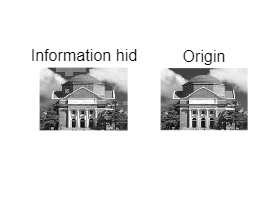

figure
subplot(1, 2, 1);
imshow(image)
title("Information hid")
subplot(1, 2, 2);
imshow(hall_gray)
title("Origin")

3.

clear all;
clc;
load("hall.mat")
load("JpegCoeff.mat")
info = dec2bin('MATLAB') - '0';

[DC, AC, len, wid, key] = hideInfo(hall_gray, info);
[image, infoAfterJPEG] = decipher(DC, AC, len, wid, key);
infoAfterJPEG

infoAfterJPEG = 6×1 char 数组
    'M'
    'A'
    'T'
    'L'
    'A'
    'B'


CR = 8 * len * wid / (length(DC) + length(AC))

CR = 6.4188

MSE = sum((image - hall_gray) .^ 2, "all") / (len * wid);
PSNR = 10 * log10(255 * 255 / MSE)

PSNR = 34.8926

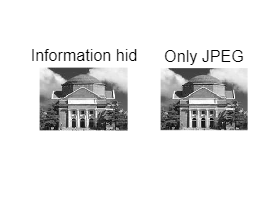


[oriDC, oriAC, oriLen, oriWid] = JPEG_encoding(hall_gray);
hall = JPEG_decoding(oriDC, oriAC, oriLen, oriWid);

figure
subplot(1, 2, 1);
imshow(image)
title("Information hid")
subplot(1, 2, 2);
imshow(hall)
title("Only JPEG")

第四部分练习题

1.(b)

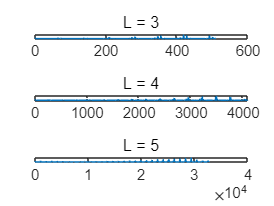

clear all;
clc;
num = 33;
feature3 = faceFeature(num, 3);
feature4 = faceFeature(num, 4);
feature5 = faceFeature(num, 5);

figure
subplot(3, 1, 1);
plot(0: 2 ^ (3 * 3) - 1, feature3)
title("L = 3");
subplot(3, 1, 2);
plot(0: 2 ^ (3 * 4) - 1, feature4);
title("L = 4");
subplot(3, 1, 3);
plot(0: 2 ^ (3 * 5) - 1, feature5);
title("L = 5");

2.

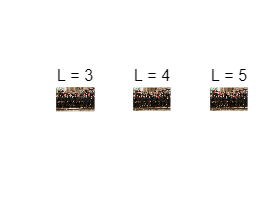

clear all;
clc;
face = imread("test.jpg");

faceSize = 75;
blockSize = 55;
pace = 5;
L = 3;
e = 0.25;
% faceRecognition(face, L, faceSize, blockSize, pace, e, num)
face3 = faceRecognition(face, 3, 75, 55, 5, 0.25, 33);
face4 = faceRecognition(face, 4, 75, 55, 5, 0.35, 33);
face5 = faceRecognition(face, 5, 75, 55, 5, 0.5, 33);
figure
subplot(1, 3, 1);
imshow(face3)
title("L = 3");
subplot(1, 3, 2);
imshow(face4)
title("L = 4");
subplot(1, 3, 3);
imshow(face5)
title("L = 5");

3.

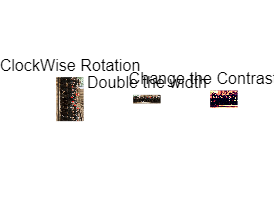

clear all;
clc;
face = imread("test.jpg");

[len, wid, ~] = size(face);
faceSize = 75;
blockSize = 55;
pace = 5;
L = 3;
e = 0.25;
% faceRecognition(face, L, faceSize, blockSize, pace, e, num)
face90 = imrotate(face, -90);
face90 = faceRecognition(face90, 3, 75, 55, 5, 0.25, 33);

% faceRecognition2(face, L, faceLen, faceWid, blockLen, blockWid, pace, e, num)
face2Wid = imresize(face, [len, 2 * wid]);
face2Wid = faceRecognition2(face2Wid, 3, 75, 150, 55, 110, 5, 0.25, 33);

faceColor = imadjust(face, [0.2, 0.3, 0; 0.6, 0.7, 1]);
faceColor = faceRecognition(faceColor, 3, 75, 55, 5, 0.5, 33);

figure
subplot(1, 3, 1);
imshow(face90)
title("ClockWise Rotation")
subplot(1, 3, 2);
imshow(face2Wid)
title("Double the width")
subplot(1, 3, 3);
imshow(faceColor)
title("Change the Contrast Ratio")

function v = faceFeature(num, L)
    v = zeros([1, 2 ^ (3 * L)]);
    for i = 1: num
        face = imread("Faces\" + string(i) + ".bmp");
        v = v + getFeature(face, L);
    end
    v = v / num;
end

function img = faceRecognition(face, L, faceSize, blockSize, pace, e, num)
    [len, wid, ~] = size(face);
    xRight = [];
    yTop = [];
    mark = [];
    feature = faceFeature(num, L);
    i = blockSize;
    while i <= len
        j = blockSize;
        while j <= wid
            u = getFeature(face(i - blockSize + 1: i, j - blockSize + 1: j, :), L);
            d = 1 - sum(sqrt(u .* feature));
            if d < e
                xRight = [xRight, i];
                yTop = [yTop, j];
                mark = [mark, 1];
            end
            j = j + pace;
        end
        i = i + pace;
    end
    xLeft = xRight - blockSize + 1;
    yBottom = yTop - blockSize + 1;
    
    for i = 1: length(mark) - 1
        for j = i + 1: length(mark)
            if mark(j)
                if (abs(xLeft(i) - xLeft(j)) <= pace || abs(xRight(i) - xRight(j)) <= pace) && ...
                        (abs(yBottom(i) - yBottom(j)) <= pace || abs(yTop(i) - yTop(j)) <= pace)
                    minXLeft = min(xLeft(i), xLeft(j));
                    minYBottom = min(yBottom(i), yBottom(j));
                    maxXRight = max(xRight(i), xRight(j));
                    maxYTop = max(yTop(i), yTop(j));
                    area = 1.5 * faceSize * faceSize;
                    if (maxYTop - minYBottom) * (maxXRight - minXLeft) < area
                        mark(j) = 0;
                        xLeft(i) = minXLeft;
                        yBottom(i) = minYBottom;
                        xRight(i) = maxXRight;
                        yTop(i) = maxYTop;
                    end
                end
            end
        end
    end
    
    xLeft = xLeft(mark == 1) + 2 * pace;
    yBottom = max(yBottom(mark == 1) + 1 * pace, 1);
    xRight = min(xRight(mark == 1) + 6 * pace, len);
    yTop = yTop(mark == 1) - 4 * pace;
    mark = mark(mark == 1);
    
    for i = 1: length(mark) - 1
        for j = i + 1: length(mark)
            if ((abs(xLeft(i) - xLeft(j)) <= 6 * pace || xLeft(j) > xLeft(i)) &&...
                (abs(xRight(i) - xRight(j)) <= 6 * pace || xRight(j) < xRight(i)) && ...
                (abs(yBottom(i) - yBottom(j)) <= 6 * pace || yBottom(j) > yBottom(i)) && ...
                (abs(yTop(i) - yTop(j)) <= 6 * pace || yTop(j) < yTop(i)))
                mark(j) = 0;
            end
        end
    end
    
    redBox = false(size(face));
    w = 1;
    for i = 1: length(mark)
        if mark(i)
            redBox(xLeft(i) - w: xLeft(i) + w, yBottom(i) : yTop(i), 1) = true;
            redBox(xRight(i) - w: min(len, xRight(i) + w), yBottom(i) : yTop(i), 1) = true;
            redBox(xLeft(i): xRight(i), yBottom(i) - w: yBottom(i) + w, 1) = true;
            redBox(xLeft(i): xRight(i), yTop(i) - w: yTop(i) + w, 1) = true;
        end
    end
    face(redBox) = 255;
    img = face;
end

function img = faceRecognition2(face, L, faceLen, faceWid, blockLen, blockWid, pace, e, num)
    [len, wid, ~] = size(face);
    xRight = [];
    yTop = [];
    mark = [];
    feature = faceFeature(num, L);
    i = blockLen;
    rate = faceWid / faceLen;
    intRate = round(rate);
    while i <= len
        j = blockWid;
        while j <= wid
            u = getFeature(face(i - blockLen + 1: i, j - blockWid + 1: j, :), L);
            d = 1 - sum(sqrt(u .* feature));
            if d < e
                xRight = [xRight, i];
                yTop = [yTop, j];
                mark = [mark, 1];
            end
            j = j + pace;
        end
        i = i + pace;
    end
    xLeft = xRight - blockLen + 1;
    yBottom = yTop - blockWid + 1;
    
    for i = 1: length(mark) - 1
        for j = i + 1: length(mark)
            if mark(j)
                if (abs(xLeft(i) - xLeft(j)) <= pace || abs(xRight(i) - xRight(j)) <= pace) && ...
                        (abs(yBottom(i) - yBottom(j)) <= rate * pace || abs(yTop(i) - yTop(j)) <= rate * pace)
                    minXLeft = min(xLeft(i), xLeft(j));
                    minYBottom = min(yBottom(i), yBottom(j));
                    maxXRight = max(xRight(i), xRight(j));
                    maxYTop = max(yTop(i), yTop(j));
                    area = 1.5 * faceLen * faceWid;
                    if (maxYTop - minYBottom) * (maxXRight - minXLeft) < area
                        mark(j) = 0;
                        xLeft(i) = minXLeft;
                        yBottom(i) = minYBottom;
                        xRight(i) = maxXRight;
                        yTop(i) = maxYTop;
                    end
                end
            end
        end
    end
    
    xLeft = xLeft(mark == 1) + 2 * pace;
    yBottom = max(yBottom(mark == 1) + intRate * pace, 1);
    xRight = min(xRight(mark == 1) + 6 * pace, len);
    yTop = yTop(mark == 1) - 4 * intRate * pace;
    mark = mark(mark == 1);
    
    for i = 1: length(mark) - 1
        for j = i + 1: length(mark)
            if ((abs(xLeft(i) - xLeft(j)) <= 6 * pace || xLeft(j) > xLeft(i)) &&...
                (abs(xRight(i) - xRight(j)) <= 6 * pace || xRight(j) < xRight(i)) && ...
                (abs(yBottom(i) - yBottom(j)) <= 6 * rate * pace || yBottom(j) > yBottom(i)) && ...
                (abs(yTop(i) - yTop(j)) <= 6 * rate * pace || yTop(j) < yTop(i)))
                mark(j) = 0;
            end
        end
    end
    
    redBox = false(size(face));
    w = 1;
    for i = 1: length(mark)
        if mark(i)
            redBox(xLeft(i) - w: xLeft(i) + w, yBottom(i) : yTop(i), 1) = true;
            redBox(xRight(i) - w: min(len, xRight(i) + w), yBottom(i) : yTop(i), 1) = true;
            redBox(xLeft(i): xRight(i), yBottom(i) - w: yBottom(i) + w, 1) = true;
            redBox(xLeft(i): xRight(i), yTop(i) - w: yTop(i) + w, 1) = true;
        end
    end
    face(redBox) = 255;
    img = face;
end

function u = getFeature(face, L)
    face = double(face);
    u = zeros([1, 2 ^ (3 * L)]);
    [len, wid, ~] = size(face);
    for j = 1: len
       for k = 1: wid
        R = floor(face(j, k, 1) * 2 ^ (L - 8));
        G = floor(face(j, k, 2) * 2 ^ (L - 8));
        B = floor(face(j, k, 3) * 2 ^ (L - 8));
        n = R * 2 ^ (2 * L) + G * 2 ^ L + B;
        u(n + 1) = u(n + 1) + 1;
       end
    end
    u = u / len / wid;
end

function res = cal(L)
    c = [];
    for i = 1: 33
        filename = sprintf("%d.bmp", i);
        face = imread("Faces\" + filename);
        [len, wid, ~] = size(face);
        c = c + [bitshift(face(:, :, 1), 2 * L), bitshift(face(:, :, 2), L), face(:, :, 3)];
    end
    res = c / len / wid;
end

function D = calD(N)
    row = 1: 2: 2 * N - 1;
    col = 0: N - 1;
    temp = cos(col.' * row * pi / (2 * N));
    temp(1, :) = sqrt(1 / 2) * ones(1, N);
    D = temp .* sqrt(2 / N);
end

function res = DCT2(M)
    [dim1, dim2] = size(M);
    res = calD(dim1) * M * calD(dim2).';
end

function res = zigzag(M)
    temp = reshape(M.', [1, 64]);
    a = [1, 2, 9, 17, 10, 3, 4, 11, 18, 25, 33, 26, 19, 12, 5, 6, ...
        13, 20, 27, 34, 41, 49, 42, 35, 28, 21, 14, 7, 8, 15, 22, 29, ...
        36, 43, 50, 57, 58, 51, 44, 37, 30, 23, 16, 24, 31, 38, 45, 52, ...
        59, 60, 53, 46, 39, 32, 40, 47, 54, 61, 62, 55, 48, 56, 63, 64];
    res = temp(a).';
end

function res = izigzag(M)
    a = [1, 2, 6, 7, 15, 16, 28, 29, 3, 5, 8, 14, 17, 27, 30, 43, ...
        4, 9, 13, 18, 26, 31, 42, 44, 10, 12, 19, 25, 32, 41, 45, 54, ...
        11, 20, 24, 33, 40, 46, 53, 55, 21, 23, 34, 39, 47, 52, 56, 61, ...
        22, 35, 38, 48, 51, 57, 60, 62, 36, 37, 49, 50, 58, 59, 63, 64];
    res = reshape(M(a), [8, 8]);
    res = res.';
end

function image_index = getImageIndex(image, QTAB)
    image_temp = double(image) - 128 .* ones(size(image));
    image_block = blockproc(image_temp, [8, 8], @(M) zigzag(round(dct2(M.data) ./ QTAB)));
    
    [len, wid, ~] = size(image_block);
    image_index = zeros([64, len * wid / 64]);
    for i = 1: len / 64
        image_index(:, (i - 1) * wid + 1: i * wid) = image_block(64 * (i - 1) + 1: 64 * i, :);
    end
end

function [DC, AC, height, width] = JPEG_encoding(image)
    load("JpegCoeff.mat")
    [height, width, ~] = size(image);
    image_index = getImageIndex(image, QTAB);
    
    DC_diff = [image_index(1, 1), image_index(1, 1: end - 1) - image_index(1, 2: end)];
    DC_category = min(ceil(log2(abs(DC_diff) + 1)), 11);
    
    DC = [];
    for i = 1: length(DC_diff)
	    DC_Huffman = DCTAB(DC_category(i) + 1, 2: DCTAB(DC_category(i) + 1, 1) + 1).';
	    DC_bin = (dec2bin(abs(DC_diff(i))) - '0').';
        if DC_diff(i) < 0
		    DC_bin = ~DC_bin;
        end
	    DC = [DC; DC_Huffman; DC_bin];
    end
    
    AC_index = image_index(2: end, :);
    AC_category = min(ceil(log2(abs(AC_index) + 1)), 10);

    ZRL = [1; 1; 1; 1; 1; 1; 1; 1; 0; 0; 1];
    EOB = [1; 0; 1; 0];
    [len, wid] = size(AC_category);
    AC = [];
    for i = 1: wid
        Run = 0;
        sixteenTimes = 0;
        for j = 1: len
            if AC_category(j, i) == 0
                Run = Run + 1;
                if Run == 16
                    sixteenTimes = sixteenTimes + 1;
                    Run = 0;
                end
            else
                while sixteenTimes > 0
                    AC = [AC; ZRL];
                    sixteenTimes = sixteenTimes - 1;
                end
                AC_Huffman = ACTAB(10 * Run + AC_category(j, i), 4: ACTAB(10 * Run + AC_category(j, i), 3) + 3).';
                AC_bin = (dec2bin(abs(AC_index(j, i))) - '0').';
                if AC_index(j, i) < 0
                    AC_bin = ~AC_bin;
                end
                AC = [AC; AC_Huffman; AC_bin];
                Run = 0;
            end
        end
        AC = [AC; EOB];
    end
end

function [DC, AC, height, width] = JPEG_encoding2(image)
    load("JpegCoeff.mat")
    [height, width, ~] = size(image);
    image_index = getImageIndex(image, QTAB ./ 2);
    
    DC_diff = [image_index(1, 1), image_index(1, 1: end - 1) - image_index(1, 2: end)];
    DC_category = min(ceil(log2(abs(DC_diff) + 1)), 11);
    
    DC = [];
    for i = 1: length(DC_diff)
	    DC_Huffman = DCTAB(DC_category(i) + 1, 2: DCTAB(DC_category(i) + 1, 1) + 1).';
	    DC_bin = (dec2bin(abs(DC_diff(i))) - '0').';
        if DC_diff(i) < 0
		    DC_bin = ~DC_bin;
        end
	    DC = [DC; DC_Huffman; DC_bin];
    end
    
    AC_index = image_index(2: end, :);
    AC_category = min(ceil(log2(abs(AC_index) + 1)), 10);

    ZRL = [1; 1; 1; 1; 1; 1; 1; 1; 0; 0; 1];
    EOB = [1; 0; 1; 0];
    [len, wid] = size(AC_category);
    AC = [];
    for i = 1: wid
        Run = 0;
        sixteenTimes = 0;
        for j = 1: len
            if AC_category(j, i) == 0
                Run = Run + 1;
                if Run == 16
                    sixteenTimes = sixteenTimes + 1;
                    Run = 0;
                end
            else
                while sixteenTimes > 0
                    AC = [AC; ZRL];
                    sixteenTimes = sixteenTimes - 1;
                end
                AC_Huffman = ACTAB(10 * Run + AC_category(j, i), 4: ACTAB(10 * Run + AC_category(j, i), 3) + 3).';
                AC_bin = (dec2bin(abs(AC_index(j, i))) - '0').';
                if AC_index(j, i) < 0
                    AC_bin = ~AC_bin;
                end
                AC = [AC; AC_Huffman; AC_bin];
                Run = 0;
            end
        end
        AC = [AC; EOB];
    end
end

function image = JPEG_decoding(DC, AC, len, wid)
    load("JpegCoeff.mat")
    ZRL = [1; 1; 1; 1; 1; 1; 1; 1; 0; 0; 1];
    EOB = [1; 0; 1; 0];
    
    DC_diff = zeros([len * wid / 64, 1]);
    index = 1;
    count = 1;
    i = 2;
    while i <= length(DC)
        for j = 1: size(DCTAB, 1)
            if isequal(DC(index: i), DCTAB(j, 2: DCTAB(j, 1) + 1)')
                if j == 1
                    DC_diff(count) = 0;
                    index = i + 2;
                    i = index;
                    count = count + 1;
                    break;
                else
                    DC_bin = DC(i + 1: i + j - 1)';
                    if DC_bin(1)
                        DC_diff(count) = bin2dec(char(DC_bin + '0'));
                    else
                        DC_diff(count) = -bin2dec(char(~DC_bin + '0'));
                    end
                    index = i + j;
                    i = index;
                    count = count + 1;
                    break;
                end
            end
        end
        i = i + 1;
    end
    
    DC_index = zeros(size(DC_diff));
    DC_index(1) = DC_diff(1);
    for i = 2: size(DC_index, 1)
        DC_index(i) = DC_index(i - 1) - DC_diff(i);
    end
    
    AC_index = zeros([63, len * wid / 64]);
    index = 1;
    rowCount = 1;
    colCount = 1;
    i = 2;
    while i <= length(AC)
        if isequal(AC(index: i), EOB)
            colCount = colCount + 1;
            rowCount = 1;
            index = i + 1;
            i = index;
        elseif isequal(AC(index: i), ZRL)
            rowCount = rowCount + 16;
            index = i + 1;
            i = index;
        else
            for j = 1: size(ACTAB, 1)
                if isequal(AC(index: i), ACTAB(j, 4: ACTAB(j, 3) + 3)')
                    rowCount = rowCount + ACTAB(j, 1);
                    AC_bin = AC(i + 1: i + ACTAB(j, 2))';
                    if AC_bin(1)
                        AC_index(rowCount, colCount) = bin2dec(char(AC_bin + '0'));
                    else
                        AC_index(rowCount, colCount) = -bin2dec(char(~AC_bin + '0'));
                    end
                    rowCount = rowCount + 1;
                    index = i + ACTAB(j, 2) + 1;
                    i = index;
                    break;
                end
            end
        end
        i = i + 1;
    end
    image_index = [DC_index'; AC_index];
    image_block = zeros([len * 8, wid / 8]);
    % 一次从image_index搬wid / 8(168 / 8 = 21)个块到image_block
    for i = 1: len / 8
	    image_block((i - 1) * 64 + 1: i * 64, :) = image_index(:, (i - 1) .* wid / 8 + 1: i * wid / 8);
    end
    
    image = uint8(blockproc(image_block, [64, 1], @(M)(idct2(izigzag(M.data) .* QTAB))) + 128);
end

function image = JPEG_decoding2(DC, AC, len, wid)
    load("JpegCoeff.mat")
    ZRL = [1; 1; 1; 1; 1; 1; 1; 1; 0; 0; 1];
    EOB = [1; 0; 1; 0];
    
    DC_diff = zeros([len * wid / 64, 1]);
    index = 1;
    count = 1;
    i = 2;
    while i <= length(DC)
        for j = 1: size(DCTAB, 1)
            if isequal(DC(index: i), DCTAB(j, 2: DCTAB(j, 1) + 1)')
                if j == 1
                    DC_diff(count) = 0;
                    index = i + 2;
                    i = index;
                    count = count + 1;
                    break;
                else
                    DC_bin = DC(i + 1: i + j - 1)';
                    if DC_bin(1)
                        DC_diff(count) = bin2dec(char(DC_bin + '0'));
                    else
                        DC_diff(count) = -bin2dec(char(~DC_bin + '0'));
                    end
                    index = i + j;
                    i = index;
                    count = count + 1;
                    break;
                end
            end
        end
        i = i + 1;
    end
    
    DC_index = zeros(size(DC_diff));
    DC_index(1) = DC_diff(1);
    for i = 2: size(DC_index, 1)
        DC_index(i) = DC_index(i - 1) - DC_diff(i);
    end
    
    AC_index = zeros([63, len * wid / 64]);
    index = 1;
    rowCount = 1;
    colCount = 1;
    i = 2;
    while i <= length(AC)
        if isequal(AC(index: i), EOB)
            colCount = colCount + 1;
            rowCount = 1;
            index = i + 1;
            i = index;
        elseif isequal(AC(index: i), ZRL)
            rowCount = rowCount + 16;
            index = i + 1;
            i = index;
        else
            for j = 1: size(ACTAB, 1)
                if isequal(AC(index: i), ACTAB(j, 4: ACTAB(j, 3) + 3)')
                    rowCount = rowCount + ACTAB(j, 1);
                    AC_bin = AC(i + 1: i + ACTAB(j, 2))';
                    if AC_bin(1)
                        AC_index(rowCount, colCount) = bin2dec(char(AC_bin + '0'));
                    else
                        AC_index(rowCount, colCount) = -bin2dec(char(~AC_bin + '0'));
                    end
                    rowCount = rowCount + 1;
                    index = i + ACTAB(j, 2) + 1;
                    i = index;
                    break;
                end
            end
        end
        i = i + 1;
    end
    image_index = [DC_index'; AC_index];
    image_block = zeros([len * 8, wid / 8]);
    % 一次从image_index搬wid / 8(168 / 8 = 21)个块到image_block
    for i = 1: len / 8
	    image_block((i - 1) * 64 + 1: i * 64, :) = image_index(:, (i - 1) .* wid / 8 + 1: i * wid / 8);
    end
    
    image = uint8(blockproc(image_block, [64, 1], @(M)(idct2(izigzag(M.data) .* QTAB ./ 2))) + 128);
end

function [DC, AC, len, wid, key] = hideInfo(image, info)
    load("JpegCoeff.mat")
    image_temp = double(image) - 128 .* ones(size(image));
    image_block = blockproc(image_temp, [8, 8], @(M) round(dct2(M.data) ./ QTAB));
    key = false(size(image_block));
    [len, wid, ~] = size(info);
    i = 1;
    j = 1;
    while j <= len * wid
        if image_block(i) == info(j)
            image_block(i) = bitset(abs(image_block(i)), 1, info(j));
            key(i) = true;
            j = j + 1;
        end
        i = i + 1;
    end
    
    image_block = blockproc(image_block, [8, 8], @(M) zigzag(M.data));
    
    [len, wid, ~] = size(image_block);
    image_index = zeros([64, len * wid / 64]);
    for i = 1: len / 64
        image_index(:, (i - 1) * wid + 1: i * wid) = image_block(64 * (i - 1) + 1: 64 * i, :);
    end
    
    DC_diff = [image_index(1, 1), image_index(1, 1: end - 1) - image_index(1, 2: end)];
    DC_category = min(ceil(log2(abs(DC_diff) + 1)), 11);
    
    DC = [];
    for i = 1: length(DC_diff)
        DC_Huffman = DCTAB(DC_category(i) + 1, 2: DCTAB(DC_category(i) + 1, 1) + 1).';
        DC_bin = (dec2bin(abs(DC_diff(i))) - '0').';
        if DC_diff(i) < 0
	        DC_bin = ~DC_bin;
        end
        DC = [DC; DC_Huffman; DC_bin];
    end
    
    AC_index = image_index(2: end, :);
    AC_category = min(ceil(log2(abs(AC_index) + 1)), 10);
    
    ZRL = [1; 1; 1; 1; 1; 1; 1; 1; 0; 0; 1];
    EOB = [1; 0; 1; 0];
    [len, wid] = size(AC_category);
    AC = [];
    for i = 1: wid
        Run = 0;
        sixteenTimes = 0;
        for j = 1: len
            if AC_category(j, i) == 0
                Run = Run + 1;
                if Run == 16
                    sixteenTimes = sixteenTimes + 1;
                    Run = 0;
                end
            else
                while sixteenTimes > 0
                    AC = [AC; ZRL];
                    sixteenTimes = sixteenTimes - 1;
                end
                AC_Huffman = ACTAB(10 * Run + AC_category(j, i), 4: ACTAB(10 * Run + AC_category(j, i), 3) + 3).';
                AC_bin = (dec2bin(abs(AC_index(j, i))) - '0').';
                if AC_index(j, i) < 0
                    AC_bin = ~AC_bin;
                end
                AC = [AC; AC_Huffman; AC_bin];
                Run = 0;
            end
        end
        AC = [AC; EOB];
    end
    [len, wid, ~] = size(image);
end

function [image, info] = decipher(DC, AC, len, wid, key)
    load("JpegCoeff.mat")
    DC_diff = zeros([len * wid / 64, 1]);
    index = 1;
    count = 1;
    i = 2;
    ZRL = [1; 1; 1; 1; 1; 1; 1; 1; 0; 0; 1];
    EOB = [1; 0; 1; 0];
    while i <= length(DC)
        for j = 1: size(DCTAB, 1)
            if isequal(DC(index: i), DCTAB(j, 2: DCTAB(j, 1) + 1)')
                if j == 1
                    DC_diff(count) = 0;
                    index = i + 2;
                    i = index;
                    count = count + 1;
                    break;
                else
                    DC_bin = DC(i + 1: i + j - 1)';
                    if DC_bin(1)
                        DC_diff(count) = bin2dec(char(DC_bin + '0'));
                    else
                        DC_diff(count) = -bin2dec(char(~DC_bin + '0'));
                    end
                    index = i + j;
                    i = index;
                    count = count + 1;
                    break;
                end
            end
        end
        i = i + 1;
    end
    
    DC_index = zeros(size(DC_diff));
    DC_index(1) = DC_diff(1);
    for i = 2: size(DC_index, 1)
        DC_index(i) = DC_index(i - 1) - DC_diff(i);
    end
    
    AC_index = zeros([63, len * wid / 64]);
    index = 1;
    rowCount = 1;
    colCount = 1;
    i = 2;
    while i <= length(AC)
        if isequal(AC(index: i), EOB)
            colCount = colCount + 1;
            rowCount = 1;
            index = i + 1;
            i = index;
        elseif isequal(AC(index: i), ZRL)
            rowCount = rowCount + 16;
            index = i + 1;
            i = index;
        else
            for j = 1: size(ACTAB, 1)
                if isequal(AC(index: i), ACTAB(j, 4: ACTAB(j, 3) + 3)')
                    rowCount = rowCount + ACTAB(j, 1);
                    AC_bin = AC(i + 1: i + ACTAB(j, 2))';
                    if AC_bin(1)
                        AC_index(rowCount, colCount) = bin2dec(char(AC_bin + '0'));
                    else
                        AC_index(rowCount, colCount) = -bin2dec(char(~AC_bin + '0'));
                    end
                    rowCount = rowCount + 1;
                    index = i + ACTAB(j, 2) + 1;
                    i = index;
                    break;
                end
            end
        end
        i = i + 1;
    end
    image_index = [DC_index'; AC_index];
    image_block = zeros([len * 8, wid / 8]);
    % 一次从image_index搬wid / 8(168 / 8 = 21)个块到image_block
    for i = 1: len / 8
        image_block((i - 1) * 64 + 1: i * 64, :) = image_index(:, (i - 1) .* wid / 8 + 1: i * wid / 8);
    end
    
    image_block = blockproc(image_block, [64, 1], @(M)(izigzag(M.data)));
    [len, wid, ~] = size(key);
    info = zeros([len, wid]);
    i = 1;
    j = 1;
    while i <= len * wid
        if key(i)
            info(j) = bitset(info(j), 1, bitget(image_block(i), 1));
            j = j + 1;
        end
        i = i + 1;
    end
    info = char(bin2dec(char(reshape(info(1: j - 1), [], 7) + '0')));
    
    image = uint8(blockproc(image_block, [8, 8], @(M)(idct2(M.data .* QTAB))) + 128);
end